**Построение графиков с математической модели**

B = 0.065;
C = 0.15;
M = 0.1;
R = 0.007;

sigmaMax = deg2rad(110);
alphaMax = deg2rad(45);

alpha = linspace(0, alphaMax, 50);

k_sigma = 18;

I = C*cos(max(alpha))-B;
H = R - C*sin(max(alpha));
A = sqrt(I.^2+H.^2);

E = sqrt(A.^2-R.^2);
gamma = atan2(H,I);
tetta = atan2(E,R);

lambda = pi/2 - gamma - tetta;
k = lambda - max(alpha);
D = R*lambda;
sigmaAlphaDes = 4/M*(-C+B+D+E);
sigmaPMax = sigmaMax-sigmaAlphaDes;
lambda = pi/2 - gamma - tetta;
k = lambda - alpha;
D = R*lambda;


f1 = figure;
f2 = figure;
f10 = figure;

for sigmaP = linspace(0,sigmaPMax, 5)
    I = C*cos(alpha)-B;
    H = R - C*sin(alpha);
    A = sqrt(I.^2+H.^2);
    
    E = sqrt(A.^2-R.^2);
    gamma = atan2(H,I);
    tetta = atan2(E,R);
    
    lambda = pi/2 - gamma - tetta;
    k = lambda - alpha;
    D = R*lambda;
    J = C*sin(k);
    
    sigmaAlpha = 4/M*(-C+B+D+E);

    T_out = 16.*k_sigma.*B.*C./M^2.*sin(alpha).*(1+(M*sigmaP/4-C+B)./sqrt(B.^2+C.^2-2*B.*C.*cos(alpha)));
    figure(f1);
    plot(rad2deg(alpha), T_out);
    hold on;

    max(T_out)

    figure(f2);
    plot(rad2deg(sigmaP+sigmaAlpha), T_out);
    hold on;


    F = 4/M*k_sigma*(sigmaAlpha+sigmaP);
    T = F.*J;

    figure(f10);
    plot(rad2deg(alpha), T)
    hold on;
    grid on;
    
end

ans = 50.1692

ans = 57.7120

ans = 65.2548

ans = 72.7975

ans = 80.3403

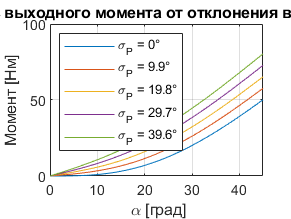


sigmaP = linspace(0,sigmaPMax, 5);

figure(f1);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(1)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(2)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(3)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(4)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(5)))/10), 176), 'Location', 'northwest');

xlabel(' \alpha [град]');
ylabel('Момент [Нм]');
title('Зависимость выходного момента от отклонения выходного звена');
grid on;

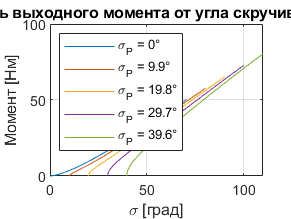

% saveas(f1, 'Torque_alpha_mat_model.svg');


figure(f2);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(1)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(2)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(3)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(4)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(5)))/10), 176), 'Location', 'northwest');

xlabel('\sigma [град]');
ylabel('Момент [Нм]');
title('Зависимость выходного момента от угла скручивания пружины');
grid on;
saveas(f2, 'Torque_sigma_mat_model.svg')

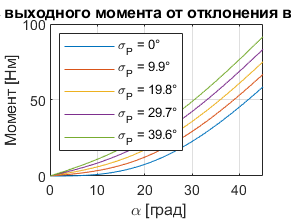



figure(f10);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(1)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(2)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(3)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(4)))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*rad2deg(sigmaP(5)))/10), 176), 'Location', 'northwest');

xlabel(' \alpha [град]');
ylabel('Момент [Нм]');
title('Зависимость выходного момента от отклонения выходного звена');
grid on;
saveas(f10, 'Torque_alpha_mat_model_2.png');

**Построение графиков с имитационной модели**

Геометрические параметры

АЛГОРИТМ РАБОТЫ программы: в положении равновесия задается преднатяжение пружины, она преднатягивается, затем к выходному звену прикладывается момент Ramp до достижения выходным звеном требуемого отклонения 45 градусов

PulleyMotor.R = 8; % mm
PulleyDrum.R = 50;
distMotor2Drum = (PulleyDrum.R+PulleyMotor.R)*1.2;
B = 65;
Roller.R = 7;
C = 150;
RollerEnd.R = 10;
SpringStiff = 18;
SpringDamp = 0.1;

sigmaMax = 110;
alphaDes = 45;
%sigmaAlpha = 50; 
ratioDrumMotor = PulleyDrum.R/PulleyMotor.R;

Геометрические параметры механизма ноги

Shank.m =  -1.59+0.036*90+0.012*180; % Масса голени
Hip.m = -2.65+0.146*90+0.014*180; % Масса бедра
Load.m = 50;                       % Масса полезной нагрузки

Shank.L = 50;        % Длина голени
Hip.L = 0.25*180;  % Длина бедра

Построение графиков

f3 = figure;
f4 = figure;
f5 = figure;

for sigmaP = linspace(0, 39.6, 5)
    
    % Defining pretension
    motorPos = sigmaP * ratioDrumMotor;

%     out = sim('Maccepa_drive_pulley_system');
    out = sim('Knee_hip_MACCEPA');

    figure(f3);
    plot(out.simout.alpha.Data, out.simout.Output_torque.Data);
    hold on;

    figure(f5);
    plot(-out.simout.sigma.Data, out.simout.Output_torque.Data);
    hold on;
end

figure(f3);
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');

xlabel(' \alpha [град]');
ylabel('Момент [Нм]');
title('Зависимость выходного момента от отклонения выходного звена');
grid on;
% saveas(f3, 'Torque_alpha_sim_model.png');

figure(f5);
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');

xlabel(' \sigma [град]');
ylabel('Момент [Нм]');
title('Зависимость выходного момента от скручивания пружины');
grid on;
% saveas(f5, 'Output_torque_sigma_sim_model.png');

figure(f4);
plot(-out.simout.sigma.Data, out.simout.M2_torque.Data);
grid on;
xlabel('\sigma [град]');
ylabel('Момент [Нм]');
title('Момент на двигателе изменения преднатяжения пружины');
% saveas(f4, 'Torque_sigma_sim_model.png')


Построение графиков VSM с ногой

% f6 = figure;

clear f7 f8 f9 f10 f11 f15
f7 = figure;
f8 = figure;
f9 = figure;
f10 = figure;
f11 = figure;
f12 = figure;
f15 = figure;

sigmaP = linspace(0, 39.6, 5);
for i = 1:size(sigmaP,2)
    
    % Defining pretension
    motorPos = deg2rad(sigmaP(i)) * ratioDrumMotor;

    out = sim('Knee_hip_MACCEPA');

    % Импорт результатов моделирования
    Spring_Torque = -out.simout.Spring_torque.Data(:,3);
    VSM_Torque = -out.simout.VSM_Torque.Data;
    human_Torque = -out.simout.tay_act.Data;
    spring_Angle = out.simout.Spring_pos.Data; % sigma
    knee_Angle = out.simout.knee_angle.Data; % alpha
    motor_Pos = out.simout.M2_pos.Data;
    motor_Torque = out.simout.M2_torque.Data;
    gravityTorque = -out.simout.gravityTorque.Data;
    time = out.tout;

    figure(f7);
    plot(rad2deg(knee_Angle), VSM_Torque, 'LineWidth', 2);
    hold on;

    figure(f15);
    plot(rad2deg(knee_Angle(50:1000)), VSM_Torque(50:1000)./knee_Angle(50:1000), 'LineWidth', 2);
    hold on;

    figure(f11);
    plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2);
    hold on;

    figure(f12);
    plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2);
    hold on;

    switch i
        case 1
            figure(f8);
            plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','g');   
            hold on;
            plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','r');
            plot(time, (VSM_Torque+human_Torque), 'LineStyle', '--', 'LineWidth', 2, 'Color','b');
            plot(time, gravityTorque, 'LineStyle', '-', 'LineWidth', 2, 'Color','k');
        case 3
            figure(f9);
            plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','g');   
            hold on;
            plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','r');
            plot(time, (VSM_Torque+human_Torque), 'LineStyle', '--', 'LineWidth', 2, 'Color','b');
            plot(time, gravityTorque, 'LineStyle', '-', 'LineWidth', 2, 'Color','k');
        case 5
            figure(f10);
            plot(time, VSM_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','g');   
            hold on;
            plot(time, human_Torque, 'LineStyle', '-', 'LineWidth', 2, 'Color','r');
            plot(time, (VSM_Torque+human_Torque), 'LineStyle', '--', 'LineWidth', 2, 'Color','b');
            plot(time, gravityTorque, 'LineStyle', '-', 'LineWidth', 2, 'Color','k');
    end
end

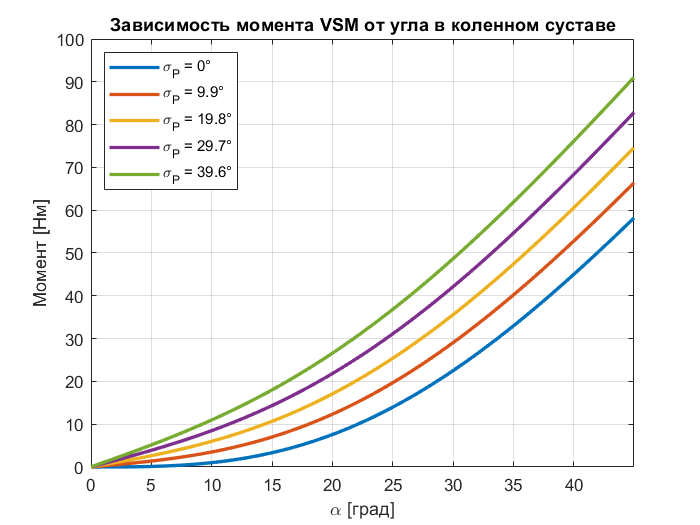



figure(f7);
xlim([0 max(rad2deg(knee_Angle))])
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('\alpha [град]');
ylabel('Момент [Нм]');
title('Зависимость момента VSM от угла в коленном суставе');

figure(f8);
grid on;
legend('VSM Torque', 'Human Torque', 'VSM+Human', 'Gravity', 'Location', 'northeast');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('График моментов при минимальной жесткости');

figure(f9);
grid on;
legend('VSM Torque', 'Human Torque', 'VSM+Human', 'Gravity', 'Location', 'northeast');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('График моментов при средней жесткости');

figure(f10);
grid on;
legend('VSM Torque', 'Human Torque', 'VSM+Human', 'Gravity', 'Location', 'northeast');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('График моментов при максимальной жесткости');

figure(f11);
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('Время [с]');
ylabel('Момент [Нм]');
title('Зависимость момента VSM от преднатяжения');

figure(f12);
grid on;
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('Время [с]');ylabel('Момент [Нм]');
title('Зависимость момента человека от преднатяжения');

figure(f15);    
grid on;
xlim([0 max(rad2deg(knee_Angle))])
sigmaP = linspace(0, 39.6, 5);
legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
       strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
xlabel('\alpha [град]');
ylabel('Жесткость [Нм/рад]');
title('Зависимость жесткости VSM от угла в колене');

% saveas(f7, 'VSM_Torque_alpha_sim_model.png');

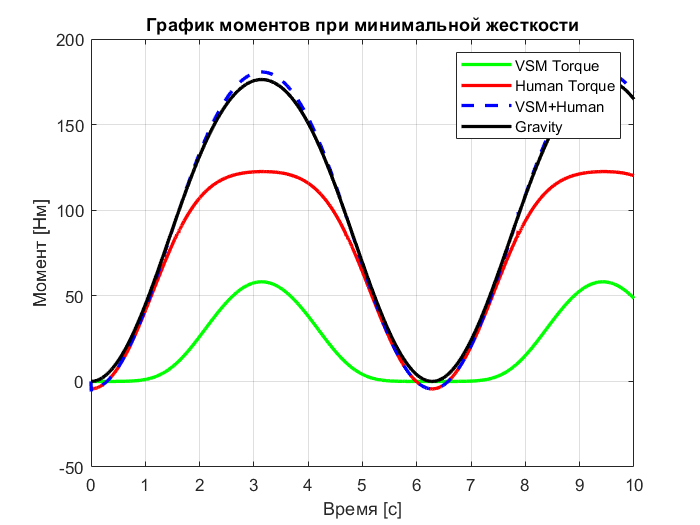

% saveas(f8, 'Torques_time_min_stiff_sim_model.png');

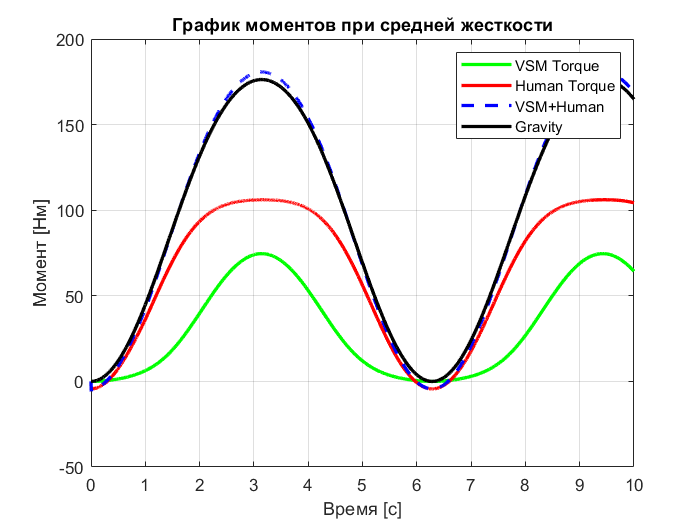

% saveas(f9, 'Torques_time_middle_stiff_sim_model.png');

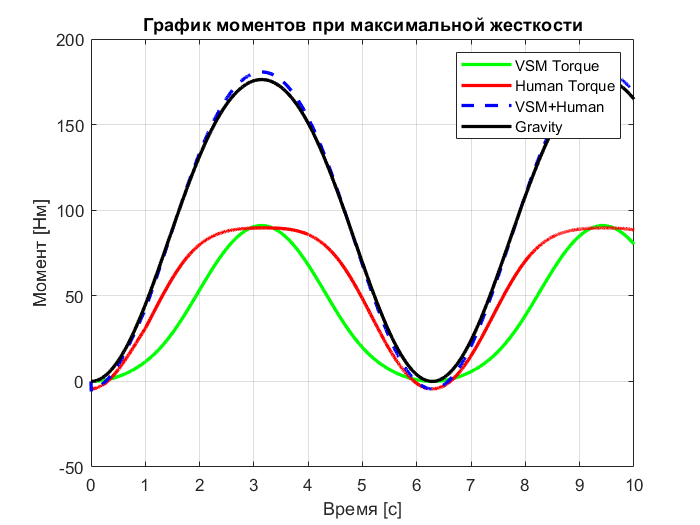

% saveas(f10, 'Torques_time_max_stiff_var_sim_model.png');

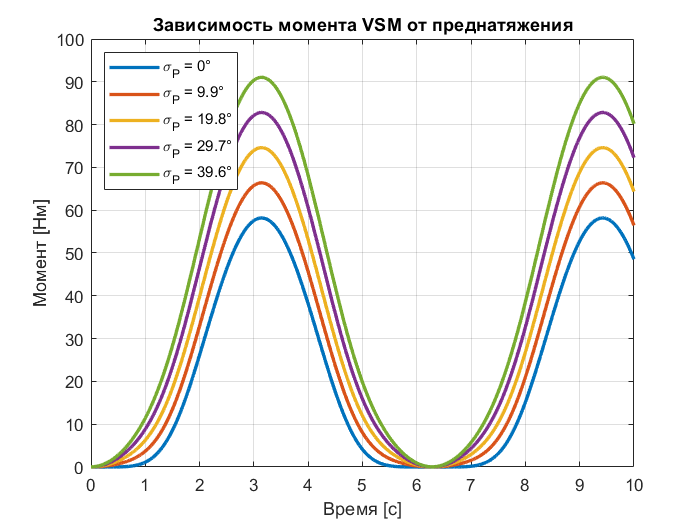

% saveas(f11, 'VSM_Torque_time_sim_model.png');

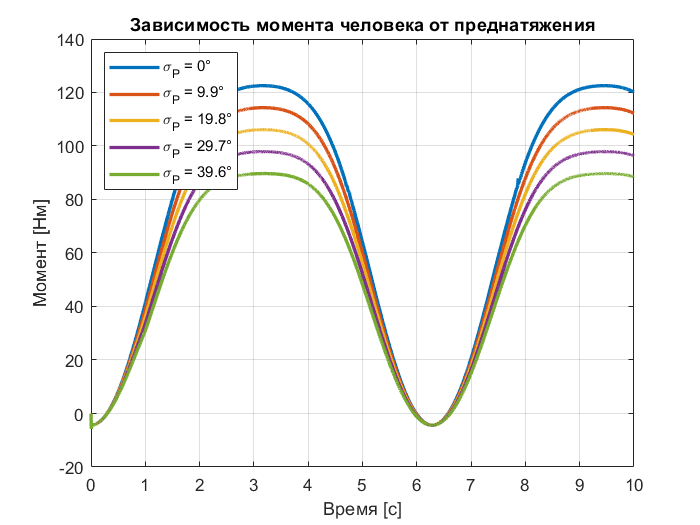

% saveas(f12, 'Human_Torque_time_sim_model.png');

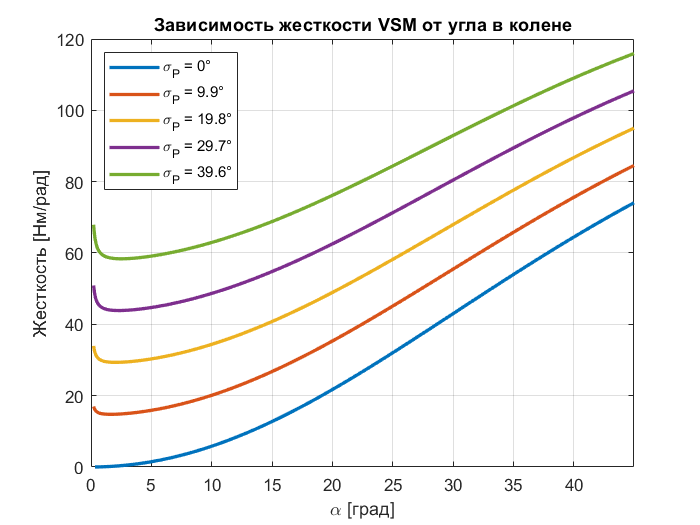

% saveas(f15, 'VSM_Stiff_alpha_sim_model.png');


% saveas(f3, 'Torque_alpha_sim_model.png');

% figure(f5);
% grid on;
% sigmaP = linspace(0, 39.6, 5);
% legend(strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(1))/10), 176),...
%        strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(2))/10), 176),...
%        strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(3))/10), 176),...
%        strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(4))/10), 176),...
%        strcat('\sigma_P', 32, '=', 32, num2str(round(10*sigmaP(5))/10), 176), 'Location', 'northwest');
% 
% xlabel(' \sigma [град]');
% ylabel('Момент [Нм]');
% title('Зависимость выходного момента от скручивания пружины');
% grid on;
% % saveas(f5, 'Output_torque_sigma_sim_model.png');
% 
% figure(f4);
% plot(-out.simout.sigma.Data, out.simout.M2_torque.Data);
% grid on;
% xlabel('\sigma [град]');
% ylabel('Момент [Нм]');
% title('Момент на двигателе изменения преднатяжения пружины');

R1 = Roller.R;
R2 = RollerEnd.R;

ac = B; ab = C;

% Подсчет А0
alpha = 0;
be = ab*cos(alpha) - ac;
oe = ab*sin(alpha)-R1;
ob = sqrt(be^2+oe^2);
df1 = sqrt(ob^2-(R2-R1)^2);

% Углы
gamma = atan2(oe,be);
theta1 = acos((R2-R1)/ob);
ksi1 = theta1+gamma-alpha;
nu1 = pi/2-ksi1;
phi1 = theta1+gamma-pi/2;
theta21 = pi/2-phi1;
lambda1 = pi/2-theta21;

qc1 = R1*tan(lambda1/2);
aq1 = ac+qc1;
br1 = R2/cos(phi1);
fr1 = R2*tan(phi1);
pr1 = ab*sin(alpha)-br1;
rq1 = qc1+df1-fr1;
ag1 = pr1*aq1/rq1;
J1 = ag1;
nf1 = R2*nu1;
A01 = R1*lambda1+df1+nf1;

% ДЛЯ ВТОРОГО ТРОСА
bh2 = R2/(R1+R2)*ob;
oh2 = R1/R2*bh2;
fh2 = sqrt(bh2^2-R2^2);
dh2 = R1/R2*fh2;
df2 = dh2+fh2;

% Углы
theta2 = acos(R1/oh2);
lambda2 = pi/2+gamma-theta2;
ksi2 = theta2-(gamma-alpha);
nu2 = pi/2-ksi2;

bi2 = R2/cos(ksi2);
ai2 = ab - bi2;
ag2 = ai2*R2/bi2;
J2 = ag2;
nf2 = R2*nu2;
A02 = R1*lambda2+df2+nf2;


% Подсчет А
alpha = 0.3871;
be = ab*cos(alpha) - ac;
oe = ab*sin(alpha)-R1;
ob = sqrt(be^2+oe^2);
df1 = sqrt(ob^2-(R2-R1)^2);

% Углы
gamma = atan2(oe,be);
theta1 = acos((R2-R1)/ob);
ksi1 = theta1+gamma-alpha;
nu1 = pi/2-ksi1;
phi1 = theta1+gamma-pi/2;
theta21 = pi/2-phi1;
lambda1 = pi/2-theta21;

qc1 = R1*tan(lambda1/2);
aq1 = ac+qc1;
br1 = R2/cos(phi1);
fr1 = R2*tan(phi1);
pr1 = ab*sin(alpha)-br1;
rq1 = qc1+df1-fr1;
ag1 = pr1*aq1/rq1;
J1 = ag1;
nf1 = R2*nu1;
A1 = R1*lambda1+df1+nf1;

% ДЛЯ ВТОРОГО ТРОСА
bh2 = R2/(R1+R2)*ob;
oh2 = R1/R2*bh2;
fh2 = sqrt(bh2^2-R2^2);
dh2 = R1/R2*fh2;
df2 = dh2+fh2;

% Углы
theta2 = acos(R1/oh2);
lambda2 = pi/2+gamma-theta2;
ksi2 = theta2-(gamma-alpha);
nu2 = pi/2-ksi2;

bi2 = R2/cos(ksi2);
ai2 = ab - bi2;
ag2 = ai2*R2/bi2;
J2 = ag2;
nf2 = R2*nu2;
A2 = R1*lambda2+df2+nf2;

% Расчет момента
sigmaAlpha1 = 2/M*(A1-A01); 
sigmaAlpha2 = 2/M*(A2-A02); 
sigmaAlpha = sigmaAlpha1 + sigmaAlpha2;
F = 2/M*k_sigma*sigmaAlpha;

T1 = F*J1;
T2 = F*J2;

T_out = T1+T2;

T_out = 10.0936